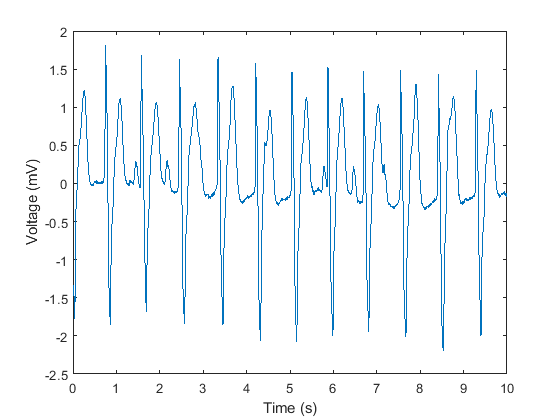

%% function by user "Said BOUREZG" to convert .dat and plot ECG signal
clear all
clc
close all
[filename, pathname] = uigetfile('*.dat', 'Open file .dat');% only image Bitmap
if isequal(filename, 0) || isequal(pathname, 0)   
    disp('File input canceled.');  
   ECG_Data = [];  
else
fid=fopen(filename,'r');
end;
time=10;
f=fread(fid,2*360*time,'ubit12');
Orig_Sig=f(1:2:length(f));
t=1:length(Orig_Sig);
t=(10/3600).*t;
Orig_Sig=(Orig_Sig-950)/250;
plot(t, Orig_Sig)
xlabel('Time (s)');
ylabel('Voltage (mV)');

## Check for tachycardia (faster than normal)

% Tachycardia is when an adult has a resting heart beat greater than 100
% beats per minute
condition=0;
BPM=length(findpeaks(Orig_Sig,'MinPeakHeight',0.8))*6;
if BPM>100
    fprintf('This patient is at risk of tachycardia');
    condition=1;
    
end

This patient is at risk of tachycardia

## Check for bradycardia (slower than normal)

% Bradycardia is when an adult has a resting heart beat less than 50 beats
% per minute
if BPM<50
    fprintf('This patient is at risk of bradycardia');
    condition=1;
end

## Check if the patient is healthy

if condition==0
    fprintf('This patient is not at risk of arrthymia');
end